## Compare the parameters for the gas/star fractions betwenn TNG100 and TNG300

 we generted fits for double gaussian based on histograms of the fgs value from both the TNG100 and TNG300 simulations.  We compare the fits between the two to determine how to merge them inot one consistent fit. 

## loading the data


global DEFAULT_MATFILE_DIR


load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_99_TNG100.mat'])
ft1=ft(5);

clear ft
load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_99_TNG300.mat'])
ft3=ft(5);


binEdge=[9 9.2500 9.5000 9.7500 10 10.2500 10.5000 10.7500 11 11.2500 11.5000];
be=9:0.25:11.5;

fgs=-5:0.001:1.5;

## plot pdf's for the two simulations 

 we plot the resultign PDFs for different stellar mass bins from the  different fits. Changes appear to be very small. 

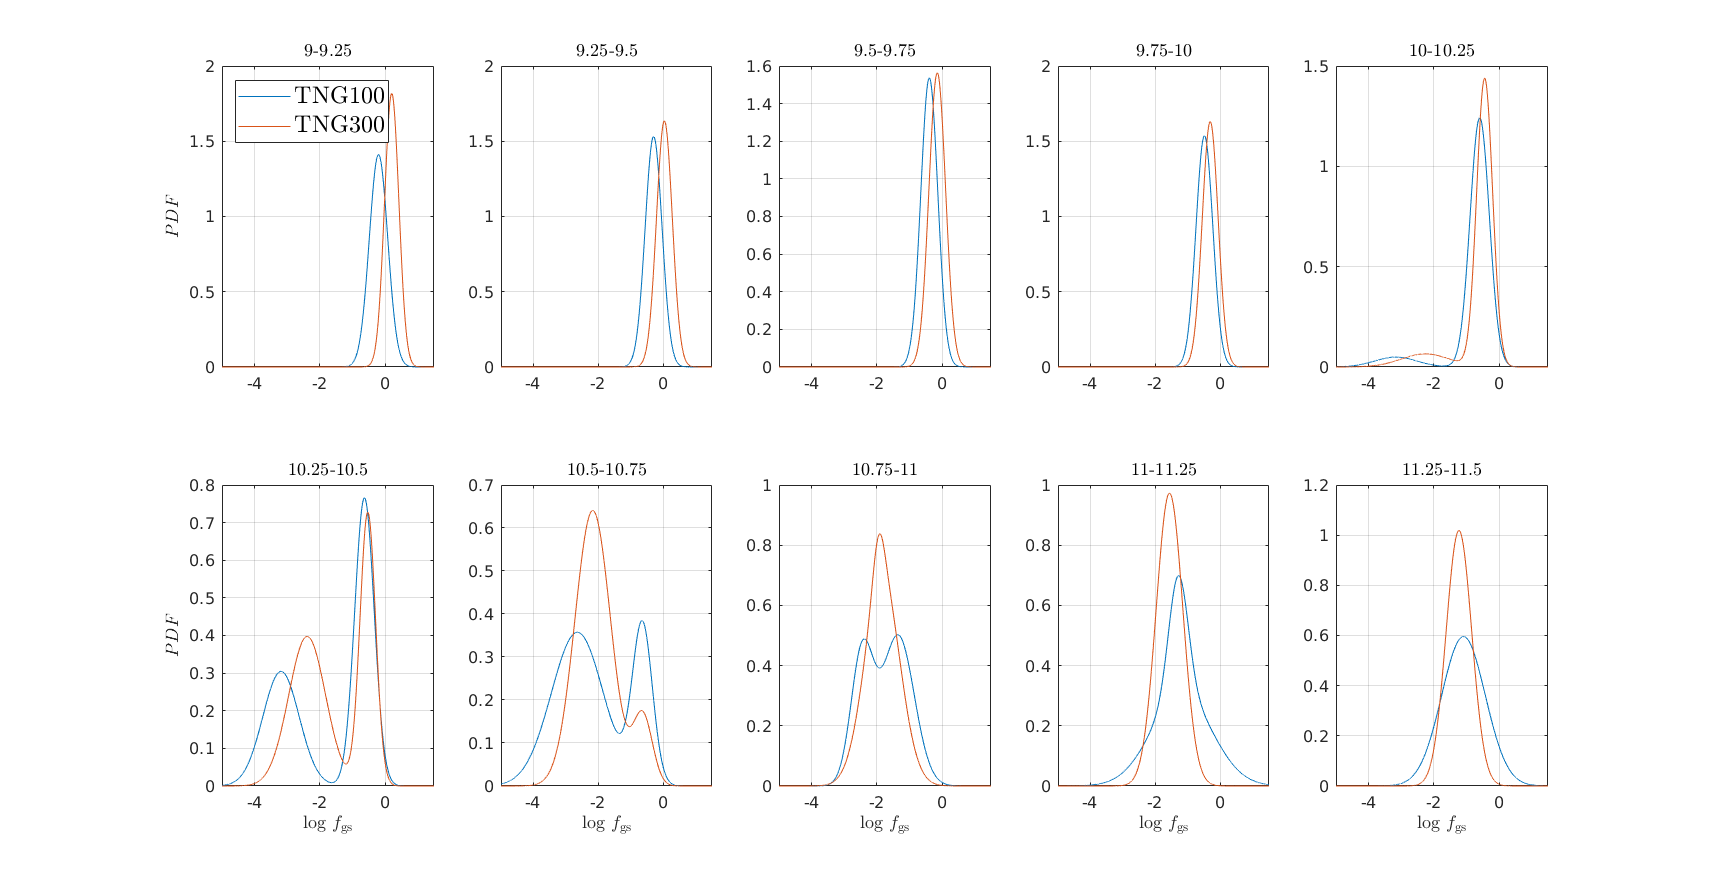



hf=figure('color','w','position',[83 433 1710 883]);

for i=1:length(ft(1).mu1)
    h=[];
    
    
    
    pdf1=ft1.a1(i).*exp(-0.5.*((fgs-ft1.mu1(i))./ft1.sig1(i)).^2) + ...
        ft1.a2(i).*exp(-0.5.*((fgs-ft1.mu2(i))./ft1.sig2(i)).^2);
    pdf1=pdf1./trapz(fgs,pdf1);
    
    pdf3=ft3.a1(i).*exp(-0.5.*((fgs-ft3.mu1(i))./ft3.sig1(i)).^2) + ...
        ft3.a2(i).*exp(-0.5.*((fgs-ft3.mu2(i))./ft3.sig2(i)).^2);
    pdf3=pdf3./trapz(fgs,pdf3);
    
    
    subplot(2,5,i)
    ax=gca;
    
    h(1)=plot(fgs,pdf1,'Displayname','TNG100');
    hold on
    h(2)=plot(fgs,pdf3,'Displayname','TNG300');

if i==1
    hl=legend(h);
    set(hl,'Interpreter','latex','fontsize',14,'Location','NorthWest');
end

grid
xlim([-5 1.5])
if i>5
    xlabelmine( '$\log\,f_\mathrm{gs}$');
else
    ax.XLabel.Visible='off';
    
end
if i==1 || i==6
    ylabelmine( '$PDF$');
else
    ax.YLabel.Visible='off';
    
end
titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);


end

## lets take a look at earlier redshifts

how does the distribuition function evolve with redshift? we examine redshifts z=0.5 (snap 67) and z=1 (snap 50)

% load data  
clear ft
load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_67_TNG100.mat'])
ft15=ft(5);

clear ft
load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_50_TNG100.mat'])
ft11=ft(5);


clear ft
load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_67_TNG300.mat'])
ft35=ft(5);

clear ft
load([DEFAULT_MATFILE_DIR '/fgs_stellarMass_gaussianFit_byBin_snp_50_TNG300.mat'])
ft31=ft(5);






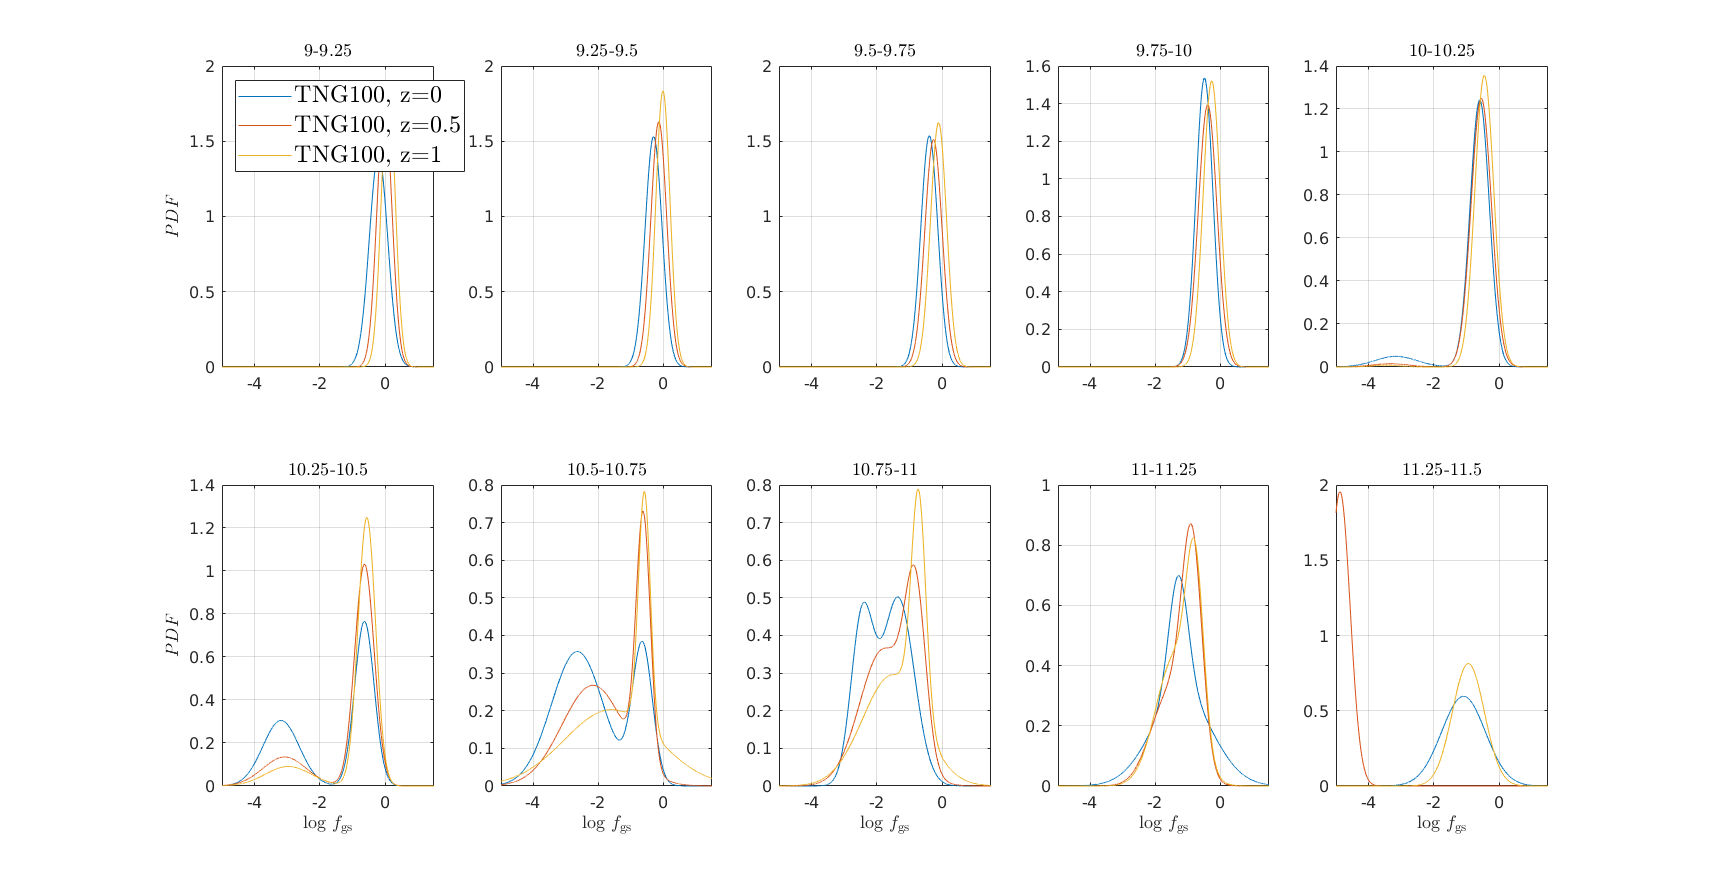

% plot tng100 redshift 

hf=figure('color','w','position',[83 433 1710 883]);

for i=1:length(ft(1).mu1)
    h=[];
    
    
    
    pdf1=ft1.a1(i).*exp(-0.5.*((fgs-ft1.mu1(i))./ft1.sig1(i)).^2) + ...
        ft1.a2(i).*exp(-0.5.*((fgs-ft1.mu2(i))./ft1.sig2(i)).^2);
    pdf1=pdf1./trapz(fgs,pdf1);
    
    pdf15=ft15.a1(i).*exp(-0.5.*((fgs-ft15.mu1(i))./ft15.sig1(i)).^2) + ...
        ft15.a2(i).*exp(-0.5.*((fgs-ft15.mu2(i))./ft15.sig2(i)).^2);
    pdf15=pdf15./trapz(fgs,pdf15);
    
    pdf11=ft11.a1(i).*exp(-0.5.*((fgs-ft11.mu1(i))./ft11.sig1(i)).^2) + ...
        ft11.a2(i).*exp(-0.5.*((fgs-ft11.mu2(i))./ft11.sig2(i)).^2);
    pdf11=pdf11./trapz(fgs,pdf11);
        
    subplot(2,5,i)
    ax=gca;
    
    h(1)=plot(fgs,pdf1,'Displayname','TNG100, z=0');
    hold on
    h(2)=plot(fgs,pdf15,'Displayname','TNG100, z=0.5');
    h(3)=plot(fgs,pdf11,'Displayname','TNG100, z=1');

if i==1
    hl=legend(h);
    set(hl,'Interpreter','latex','fontsize',14,'Location','NorthWest');
end

grid
xlim([-5 1.5])
if i>5
    xlabelmine( '$\log\,f_\mathrm{gs}$');
else
    ax.XLabel.Visible='off';
    
end
if i==1 || i==6
    ylabelmine( '$PDF$');
else
    ax.YLabel.Visible='off';
    
end
titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);


end

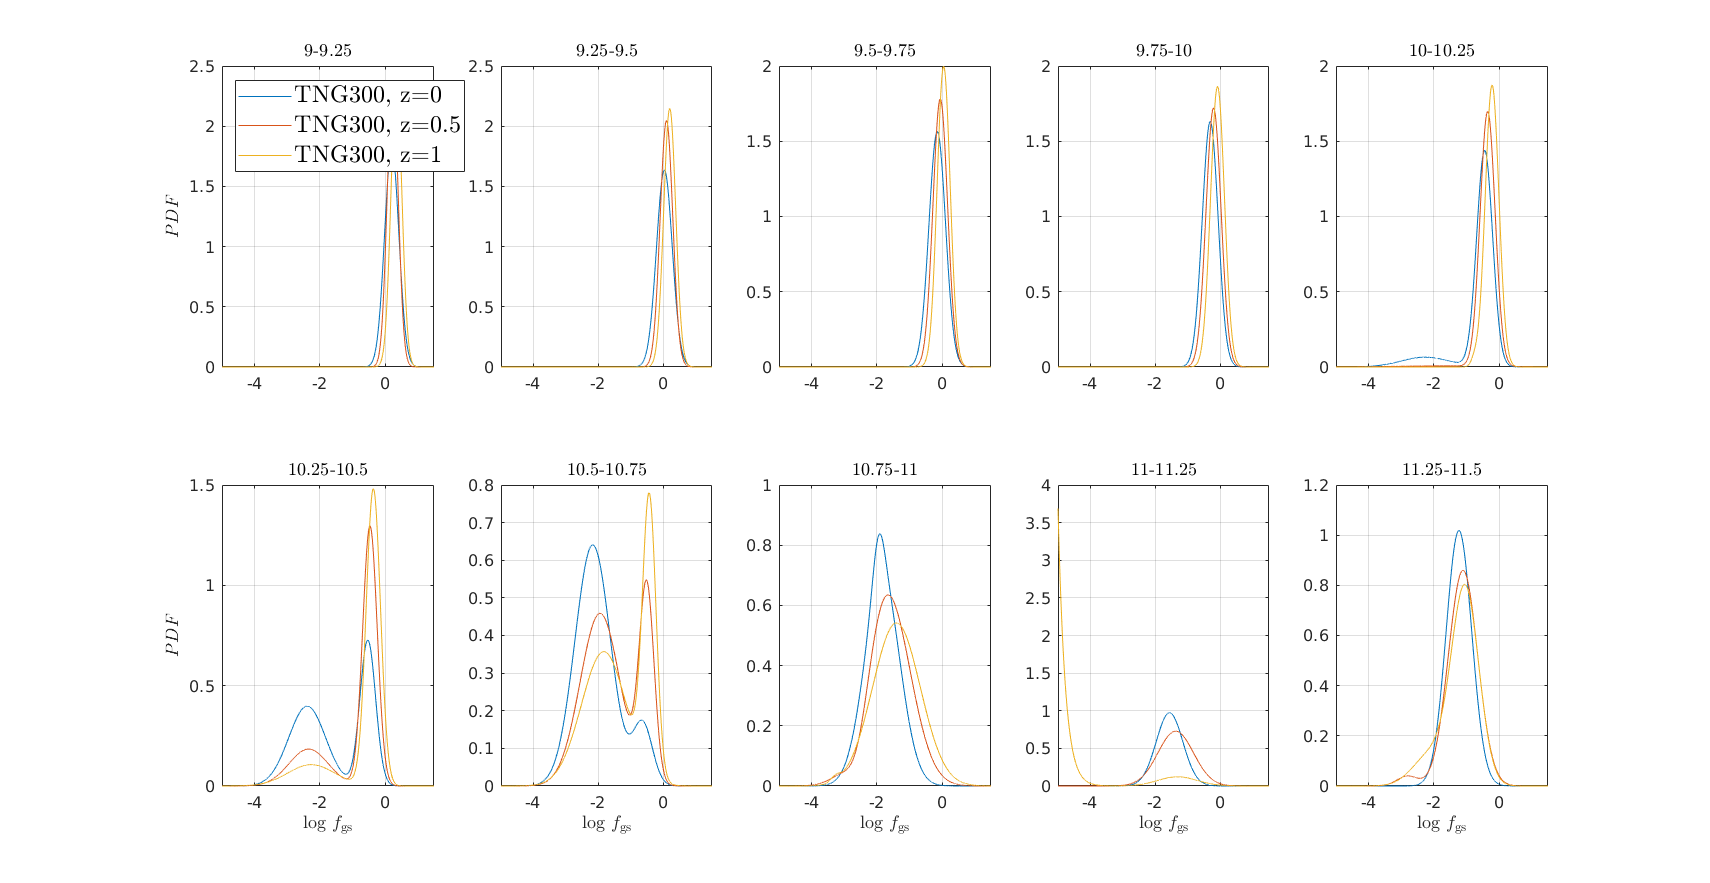

% plot tng300 redshift 

hf=figure('color','w','position',[83 433 1710 883]);

for i=1:length(ft(1).mu1)
    h=[];
    
    
    
    pdf1=ft3.a1(i).*exp(-0.5.*((fgs-ft3.mu1(i))./ft3.sig1(i)).^2) + ...
        ft3.a2(i).*exp(-0.5.*((fgs-ft3.mu2(i))./ft3.sig2(i)).^2);
    pdf1=pdf1./trapz(fgs,pdf1);
    
    pdf15=ft35.a1(i).*exp(-0.5.*((fgs-ft35.mu1(i))./ft35.sig1(i)).^2) + ...
        ft35.a2(i).*exp(-0.5.*((fgs-ft35.mu2(i))./ft35.sig2(i)).^2);
    pdf15=pdf15./trapz(fgs,pdf15);
    
    pdf11=ft31.a1(i).*exp(-0.5.*((fgs-ft31.mu1(i))./ft31.sig1(i)).^2) + ...
        ft31.a2(i).*exp(-0.5.*((fgs-ft31.mu2(i))./ft31.sig2(i)).^2);
    pdf11=pdf11./trapz(fgs,pdf11);
        
    subplot(2,5,i)
    ax=gca;
    
    h(1)=plot(fgs,pdf1,'Displayname','TNG300, z=0');
    hold on
    h(2)=plot(fgs,pdf15,'Displayname','TNG300, z=0.5');
    h(3)=plot(fgs,pdf11,'Displayname','TNG300, z=1');

if i==1
    hl=legend(h);
    set(hl,'Interpreter','latex','fontsize',14,'Location','NorthWest');
end

grid
xlim([-5 1.5])
if i>5
    xlabelmine( '$\log\,f_\mathrm{gs}$');
else
    ax.XLabel.Visible='off';
    
end
if i==1 || i==6
    ylabelmine( '$PDF$');
else
    ax.YLabel.Visible='off';
    
end
titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);


end

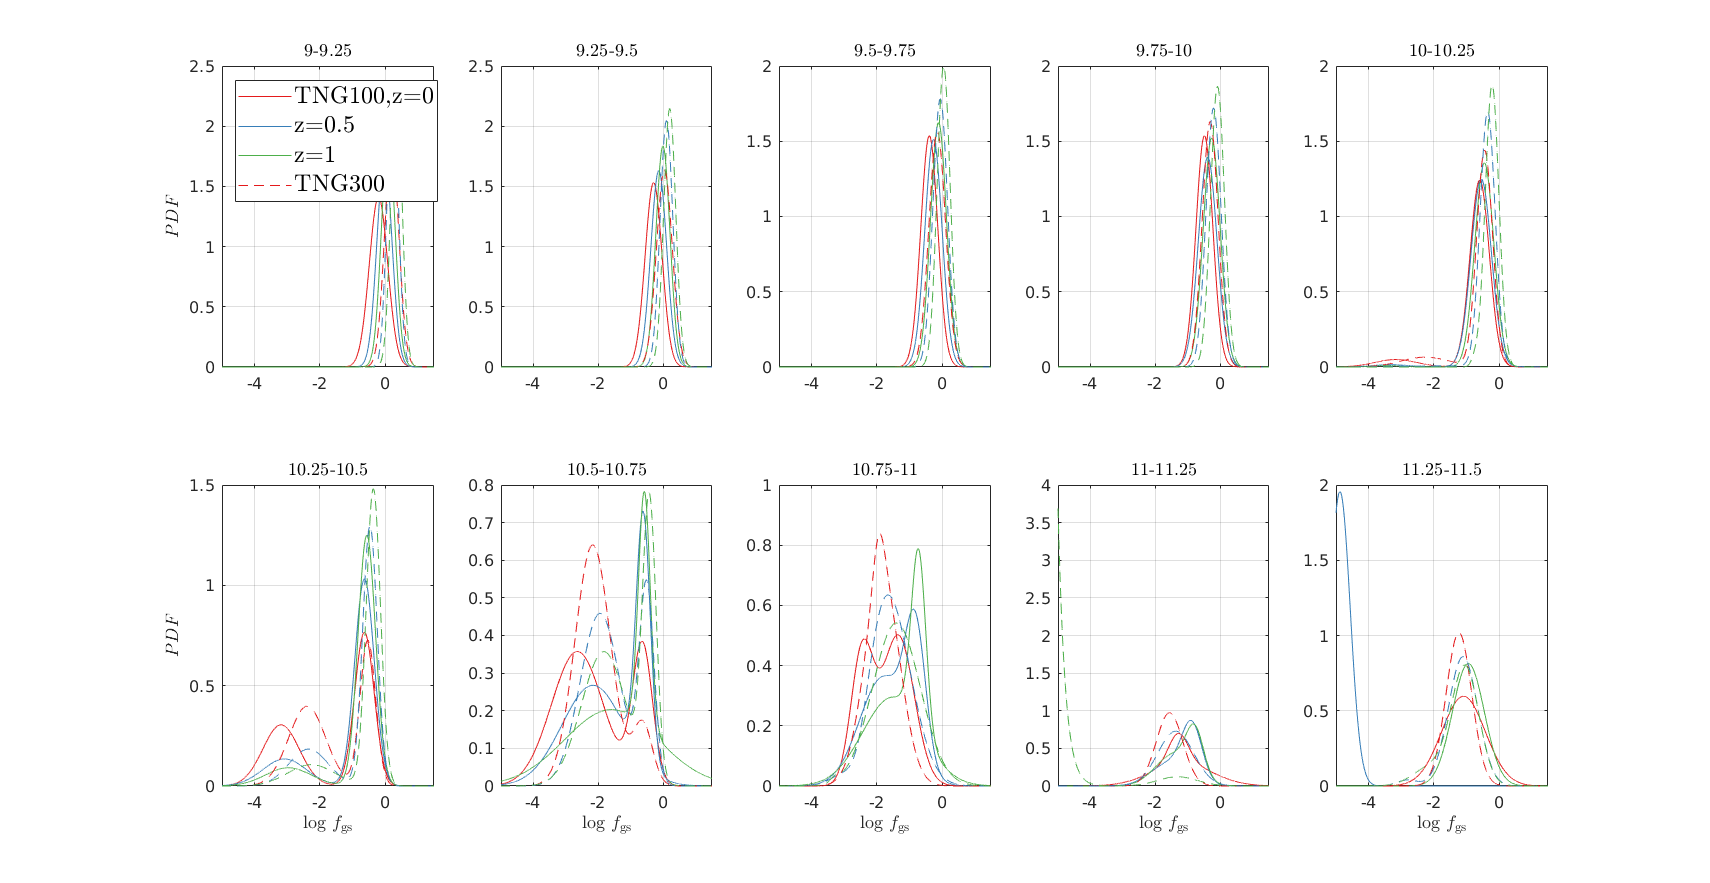

% plot אמע100 & tng300 redshift 

hf=figure('color','w','position',[83 433 1710 883]);
cc=brewermap(5,'Set1');

for i=1:length(ft(1).mu1)
    h=[];
    
     pdf1=ft1.a1(i).*exp(-0.5.*((fgs-ft1.mu1(i))./ft1.sig1(i)).^2) + ...
        ft1.a2(i).*exp(-0.5.*((fgs-ft1.mu2(i))./ft1.sig2(i)).^2);
    pdf1=pdf1./trapz(fgs,pdf1);
    
    pdf15=ft15.a1(i).*exp(-0.5.*((fgs-ft15.mu1(i))./ft15.sig1(i)).^2) + ...
        ft15.a2(i).*exp(-0.5.*((fgs-ft15.mu2(i))./ft15.sig2(i)).^2);
    pdf15=pdf15./trapz(fgs,pdf15);
    
    pdf11=ft11.a1(i).*exp(-0.5.*((fgs-ft11.mu1(i))./ft11.sig1(i)).^2) + ...
        ft11.a2(i).*exp(-0.5.*((fgs-ft11.mu2(i))./ft11.sig2(i)).^2);
    pdf11=pdf11./trapz(fgs,pdf11);
        
    
    
    pdf3=ft3.a1(i).*exp(-0.5.*((fgs-ft3.mu1(i))./ft3.sig1(i)).^2) + ...
        ft3.a2(i).*exp(-0.5.*((fgs-ft3.mu2(i))./ft3.sig2(i)).^2);
    pdf3=pdf3./trapz(fgs,pdf3);
    
    pdf35=ft35.a1(i).*exp(-0.5.*((fgs-ft35.mu1(i))./ft35.sig1(i)).^2) + ...
        ft35.a2(i).*exp(-0.5.*((fgs-ft35.mu2(i))./ft35.sig2(i)).^2);
    pdf35=pdf35./trapz(fgs,pdf35);
    
    pdf31=ft31.a1(i).*exp(-0.5.*((fgs-ft31.mu1(i))./ft31.sig1(i)).^2) + ...
        ft31.a2(i).*exp(-0.5.*((fgs-ft31.mu2(i))./ft31.sig2(i)).^2);
    pdf31=pdf31./trapz(fgs,pdf31);
        
    subplot(2,5,i)
    ax=gca;
    
    h(1)=plot(fgs,pdf1,'Displayname','TNG100,z=0','color',cc(1,:));
    hold on
    h(2)=plot(fgs,pdf15,'Displayname','z=0.5','color',cc(2,:));
    h(3)=plot(fgs,pdf11,'Displayname','z=1','color',cc(3,:));

    h(4)=plot(fgs,pdf3,'Displayname','TNG300','color',cc(1,:),'LineStyle','--');
    h(5)=plot(fgs,pdf35,'Displayname','z=0.5','color',cc(2,:),'LineStyle','--');
    h(6)=plot(fgs,pdf31,'Displayname','z=1','color',cc(3,:),'LineStyle','--');

if i==1
    hl=legend(h(1:4));
    set(hl,'Interpreter','latex','fontsize',14,'Location','NorthWest');
end

grid
xlim([-5 1.5])
if i>5
    xlabelmine( '$\log\,f_\mathrm{gs}$');
else
    ax.XLabel.Visible='off';
    
end
if i==1 || i==6
    ylabelmine( '$PDF$');
else
    ax.YLabel.Visible='off';
    
end
titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);


end

## plot fit parameters for different histogram bins

Here we examine the results more closely - follow the parameters themselves as bin number/size is changed. In the mass bins where the fit produced a single gaussian we ignore the other fit results. 

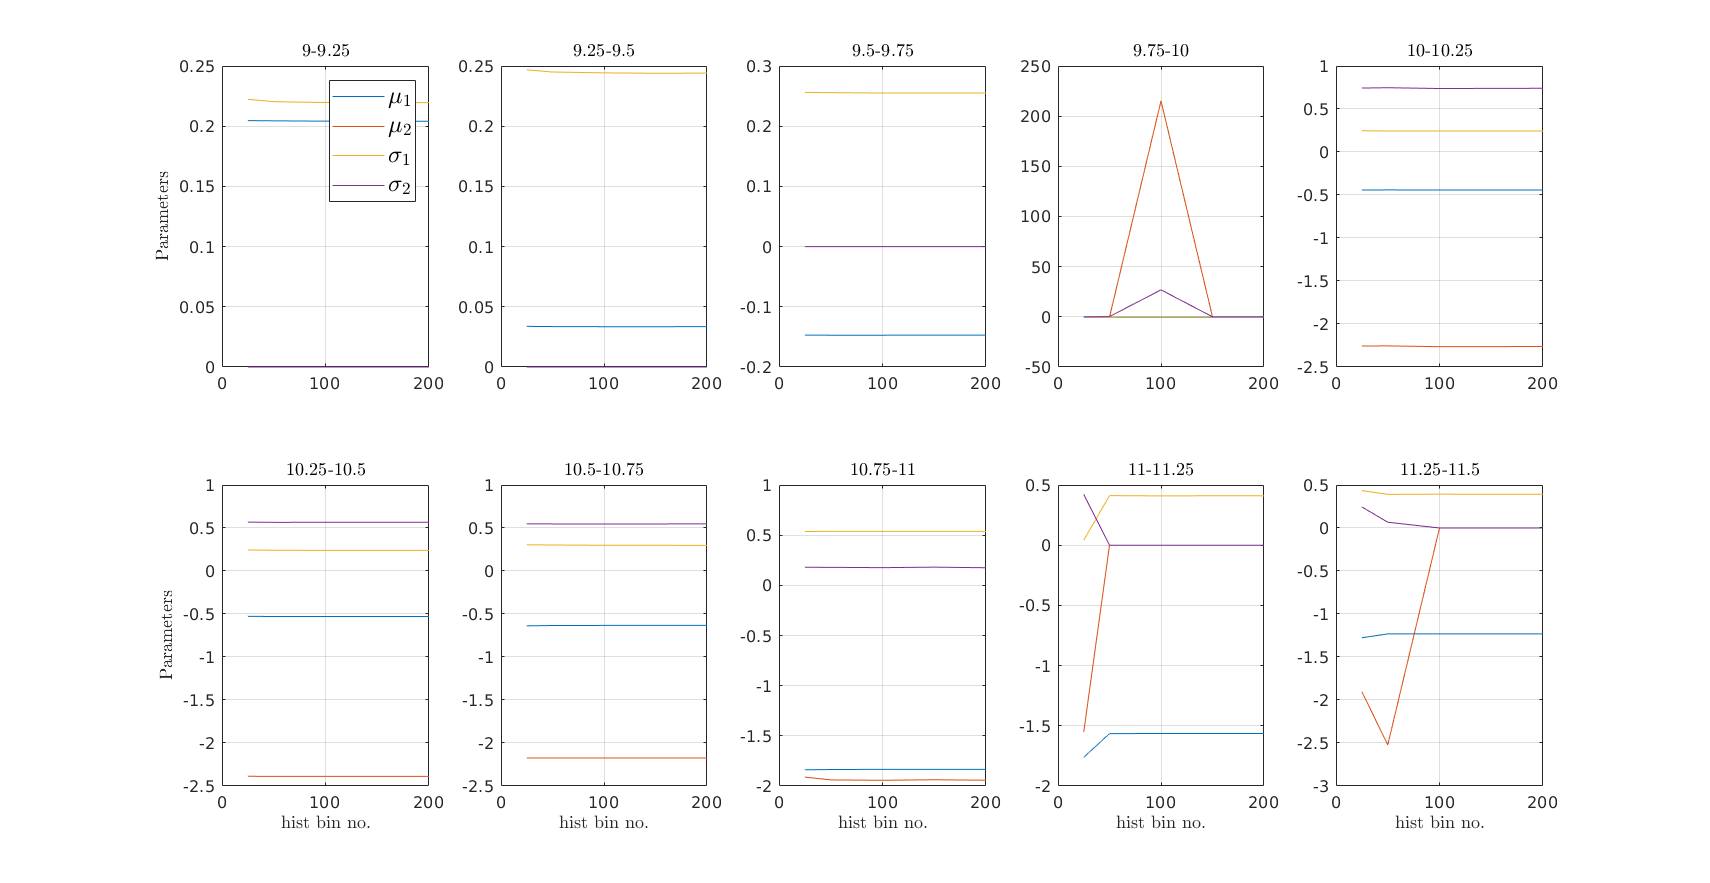


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
 
    
 
    subplot(2,5,i)
    ax=gca;
        
    for k=1:4
        h(k)=plot(xx,pars(:,k),'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

 Plot the amplitude values - these go down since the bin size is

 decreasing

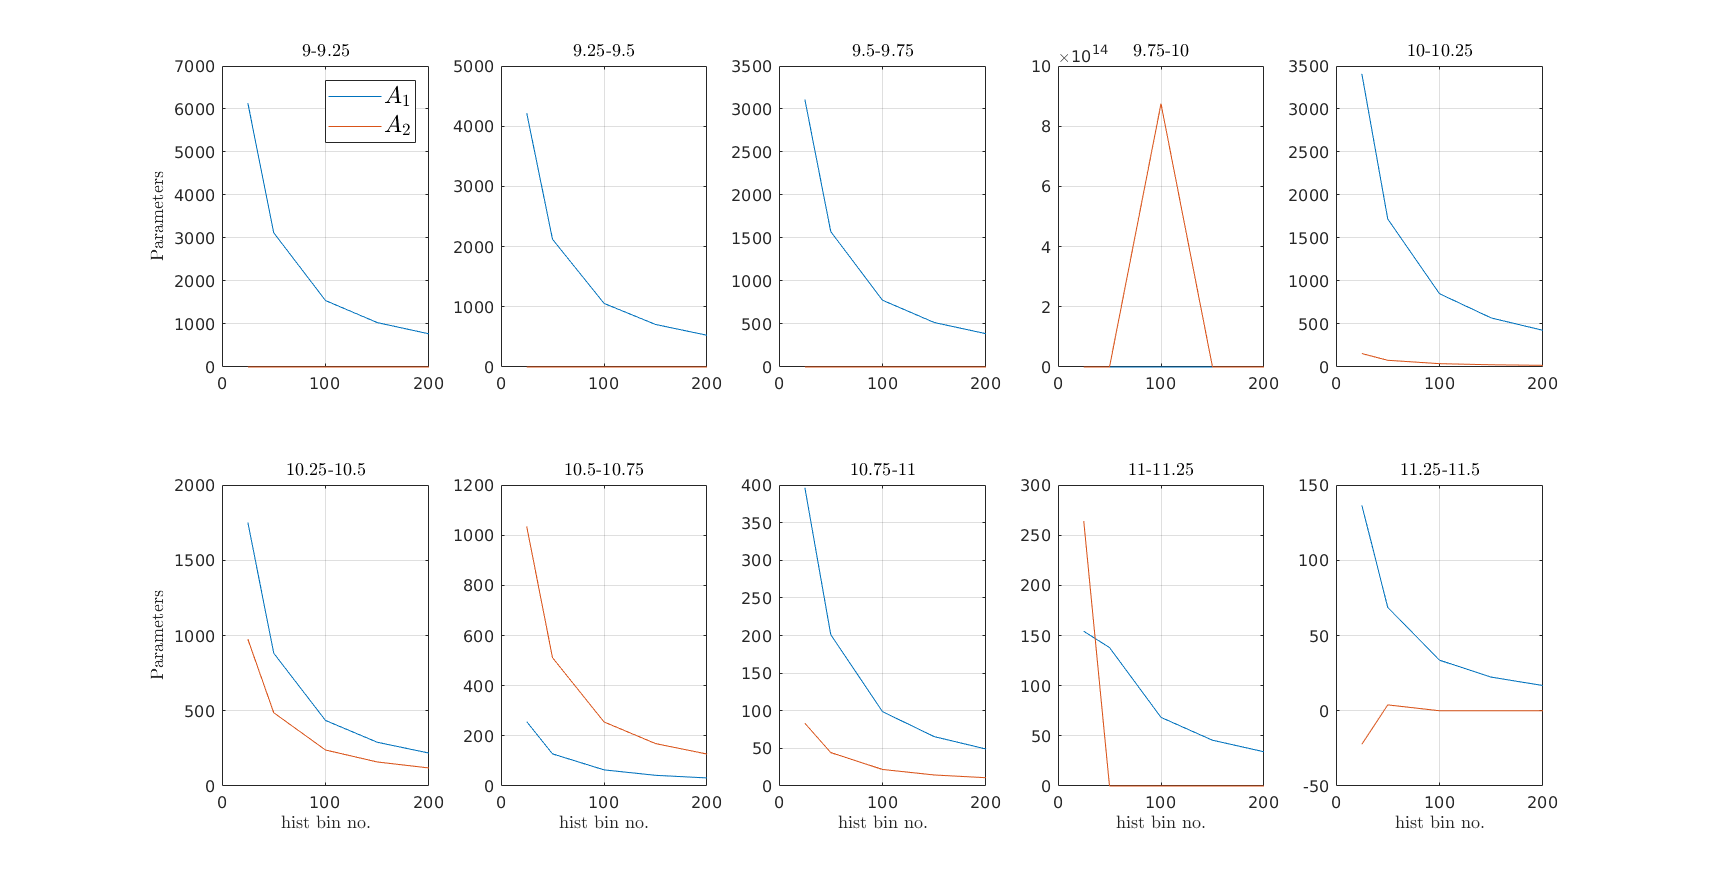


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
   
 
    subplot(2,5,i)
    ax=gca;
        
    for k=5:6
        h(k-4)=plot(xx,pars(:,k),'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

Now plot the fractional values for the fit parameters 

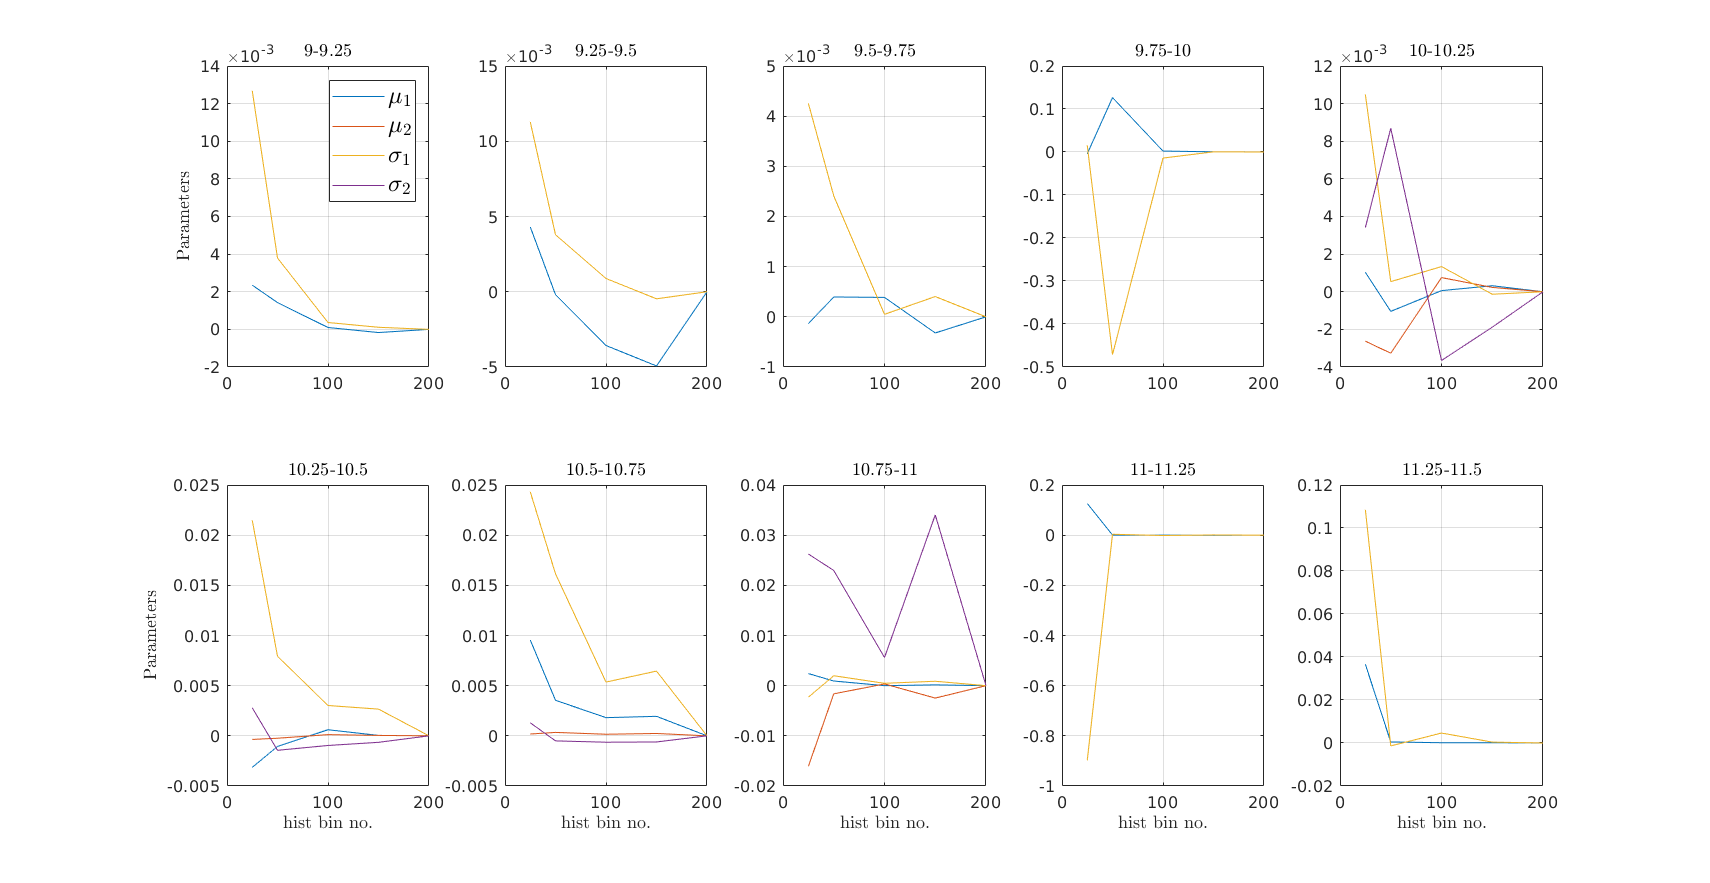


hf=figure('color','w','position',[83 433 1710 883]);
tag={'$\mu_1$','$\mu_2$','$\sigma_1$','$\sigma_2$','$A_1$','$A_2$'};


for i=1:length(ft(1).mu1)
    h=[];
    
    pars=zeros(length(ft),6);
    for k=1:length(ft)
        pars(k,1)=ft(k).mu1(i);
        pars(k,3)=ft(k).sig1(i);
        pars(k,5)=ft(k).a1(i);
        
        if ft(k).a2(i)~=0
            pars(k,2)=ft(k).mu2(i);
            pars(k,4)=ft(k).sig2(i);
            pars(k,6)=ft(k).a2(i);
        end
        xx(k)=ft(k).histBinNum;
        
    end
 
    
 
    subplot(2,5,i)
    ax=gca;
        
    for k=1:4
        h(k)=plot(xx,pars(:,k)./pars(end,k)-1,'Displayname',tag{k});
        hold on
    end
    
    if i==1
        hl=legend(h);
        set(hl,'Interpreter','latex','fontsize',14,'Location','northeast');
    end
    
    %ax.Legend.Visible='off';
    
    grid
    %xlim([-5 1.5])
    if i>5
        xlabelmine( 'hist bin no.');
    else
        ax.XLabel.Visible='off';
        
    end
    if i==1 || i==6
        ylabelmine( 'Parameters');
    else
        ax.YLabel.Visible='off';
        
    end
    titlemine([ num2str(be(i)) '-' num2str(be(i+1)) ]);
    
end

## conclusion - the fits are by and large consistent even for low bin number histograms, but there are some weird flukes we should be carful of, using the 200 bin fit is probably best. 